## Tarea 1 Control Pc.

Control de una planta hidráulica.

#### Estudiante: Juan José Torres Quiñonez.

Parámetros:

%Parámetros:
Ra=10

Ra = 10

Ki=10

Ki = 10

Kb=0.0706

Kb = 0.0706

Jl=10

Jl = 10

Jm=0.005

Jm = 0.0050

Ka=5

Ka = 5

n=1/100

n = 0.0100

a=4.52

a = 4.5200

Ks=5

Ks = 5

Kv=10

Kv = 10

Ko=50

Ko = 50

N=1

N = 1

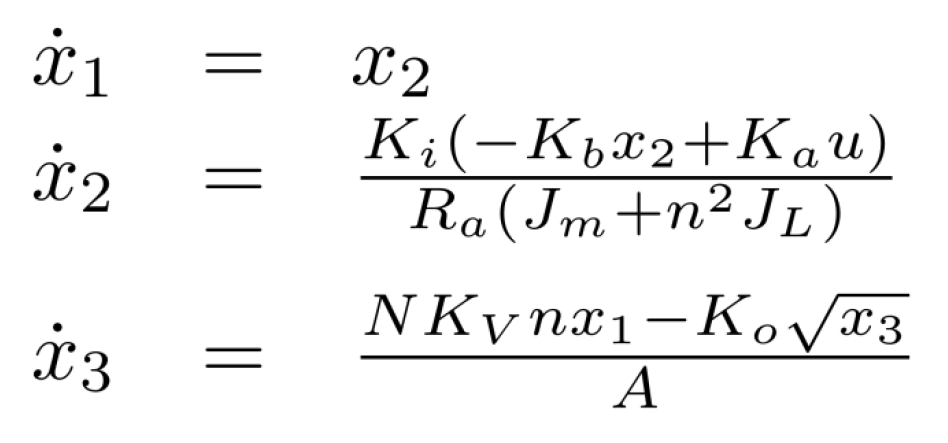

## 2.

%Punto de operación h **********************************
disp('Punto de operación h:')

Punto de operación h:


h=1

h = 1


%calculo el jacobiano del sistema en espacio de estados:
syms x [1 3]    %define x1, x2 y x3 como simbólicas
syms u

dx1=x2

$$dx1 = x_{2}$$

dx2=(Ki*(-Kb*x2+Ka*u))/(Ra*(Jm+n^2*Jl))

$$dx2 = 833.3333\,u-11.7667\,x_{2}$$

dx3=(N*Kv*n*x1-Ko*sqrt(x3))/a %representa la altura

$$dx3 = 0.0221\,x_{1}-11.0619\,\sqrt{x_{3}}$$

mat_F=[dx1;dx2;dx3]     %con parámetros numéricos

$$mat\_F = \left(\begin{array}{c} x_{2}\\ 833.3333\,u-11.7667\,x_{2}\\ 0.0221\,x_{1}-11.0619\,\sqrt{x_{3}} \end{array}\right)$$

mat_linealizada_A=jacobian(mat_F,x) %deriva respecto a x    

$$mat\_linealizada\_A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & -11.7667 & 0\\ 0.0221 & 0 & -\frac{5.5310}{{x_{3}}^{0.5000}} \end{array}\right)$$

mat_linealizada_B=jacobian(mat_F,u)  %deriva respecto a u

$$mat\_linealizada\_B = \left(\begin{array}{c} 0\\ 833.3333\\ 0 \end{array}\right)$$

%Igualo a cero, h*=0, valores de estado estacionario:
x2_ss=0

x2_ss = 0

u_ss=0      %u despejado

u_ss = 0

x3_ss=1     %referencia, punto de operacion h* (1 metro por ejemplo)

x3_ss = 1

x1_ss=(Ko*sqrt(x3_ss))/(N*Kv*n)

x1_ss = 500

sustitu_mat_lin_A=double(subs(mat_linealizada_A,x3,x3_ss)) %Se sustituye x3 simbólico por valor de referencia y se convierte el tipo de variable a double

sustitu_mat_lin_A =          0    1.0000         0
         0  -11.7667         0
    0.0221         0   -5.5310


sustitu_mat_lin_B=double(subs(mat_linealizada_B,u,u_ss))   %Se sustituye u simbólico por valor

sustitu_mat_lin_B =          0
  833.3333
         0


con eso se consiguió el sistema lineal de la forma:  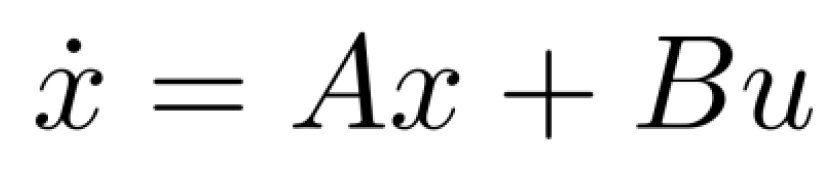

#### Diseño de control: por funcion de transferencia o espacio de estados.

la realimentación es el estado x3 y es el que busco que llegue a la referencia.

%Creo matrices de salida C y D:
C=[0 0 1]   %C debe ser estados 0 0 1

C =      0     0     1


D=0 %realimentación aunque no se "usa" en este caso se deja definida.

D = 0

#### PID y sistema en función de transferencia. 

[numerador,denom]=ss2tf(sustitu_mat_lin_A,sustitu_mat_lin_B,C,D)

numerador =          0         0         0   18.4366


denom =     1.0000   17.2976   65.0811         0


sisteTransferencia=tf(numerador,denom)    %tf es func transfencia.

sisteTransferencia =
 
           18.44
  ------------------------
  s^3 + 17.3 s^2 + 65.08 s
 
Continuous-time transfer function.
Model Properties


hago uso de PID Tuner ajustando el tiempo de respuesta entre lento y rápido, para el comportamiento transitorio entre agresivo y robusto:

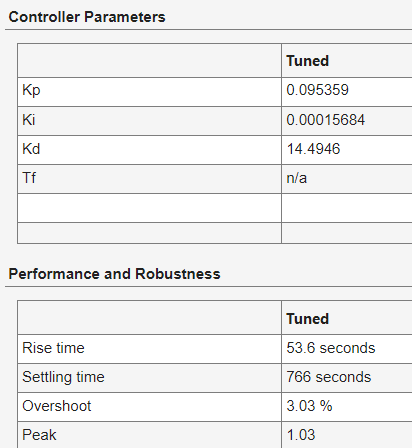

Se aprecia que por inestabilidad vale huevo.******

#### Gráfica PID de simulink.

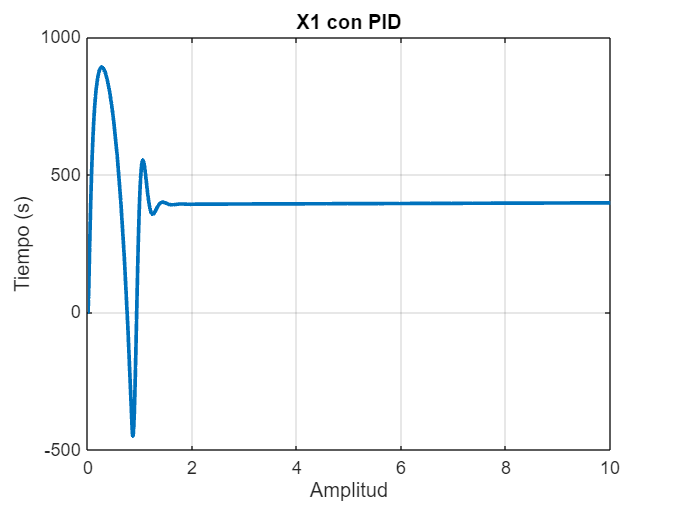

figure; %subplot(3,1,1); 
plot(out.tout  ,out.ScopeData.signals(1).values,'LineWidth', 2); title('X1 con PID');
xlabel('Amplitud'); ylabel('Tiempo (s)'); grid on;

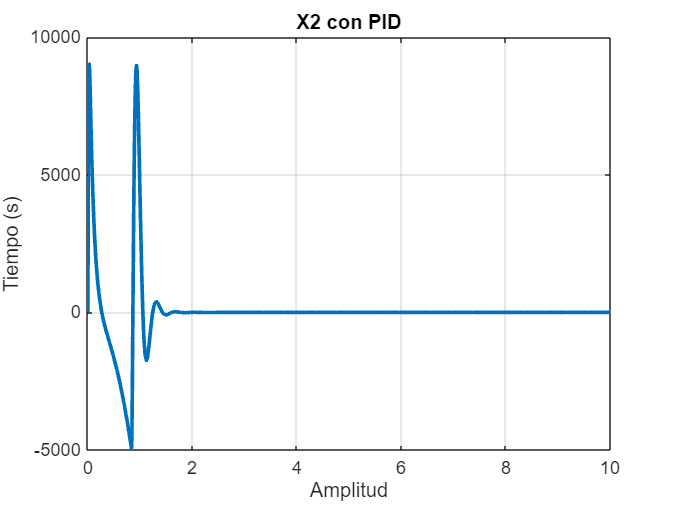

%subplot(3,1,2); 
plot(out.tout  ,out.ScopeData.signals(2).values,'LineWidth', 2); title('X2 con PID');
xlabel('Amplitud'); ylabel('Tiempo (s)'); grid on;

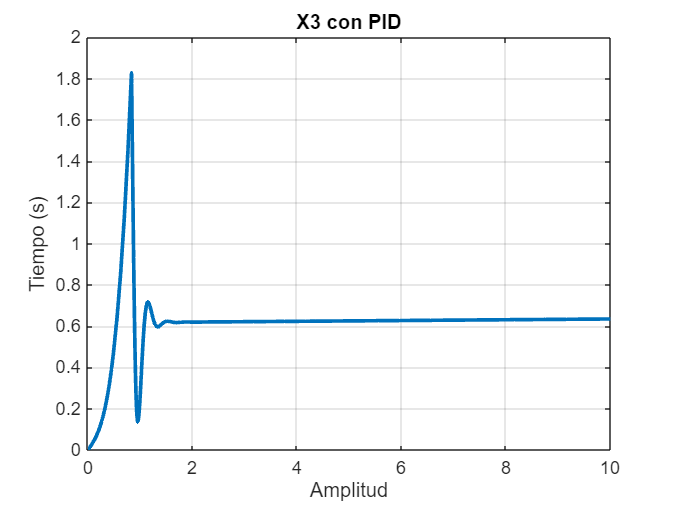

%subplot(3,1,3); 
plot(out.tout  ,out.ScopeData.signals(3).values,'LineWidth', 2); title('X3 con PID');
xlabel('Amplitud'); ylabel('Tiempo (s)'); grid on;
hold off

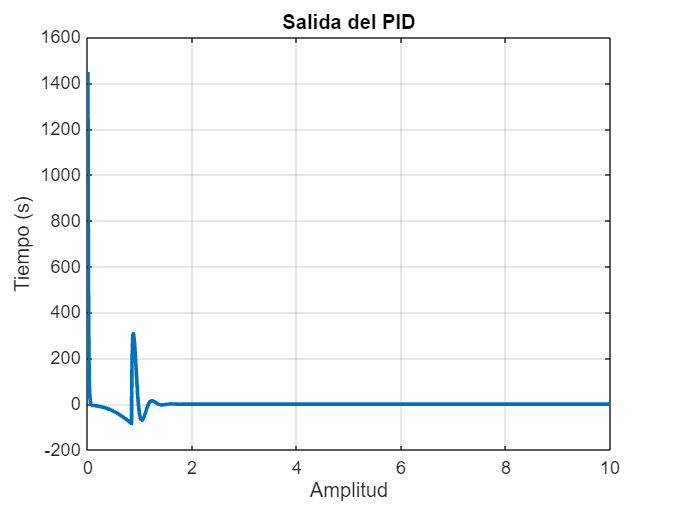

figure;
plot(out.ScopeData2.time  ,out.ScopeData2.signals.values,'LineWidth', 2); title('Salida del PID');
xlabel('Amplitud'); ylabel('Tiempo (s)'); grid on;

Hasta aquí fue la configuración del PID.

En el modo no lineal lo siguiente no funciona bien pero bueno:

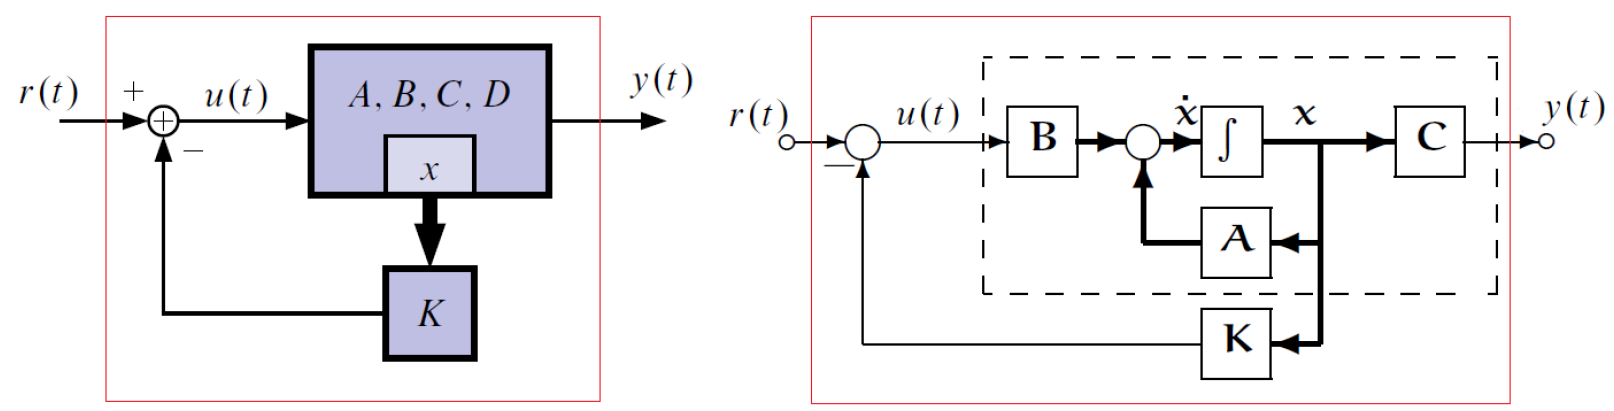

#### Realimentación de estados.

Debe tenerse en cuenta la asignación de polos.

La tabla contiene los polos cuya característica es que fueron calculados para que den una respuesta de fase lineal es útil para evitar problemas de inestabilidad en sistemas de control.

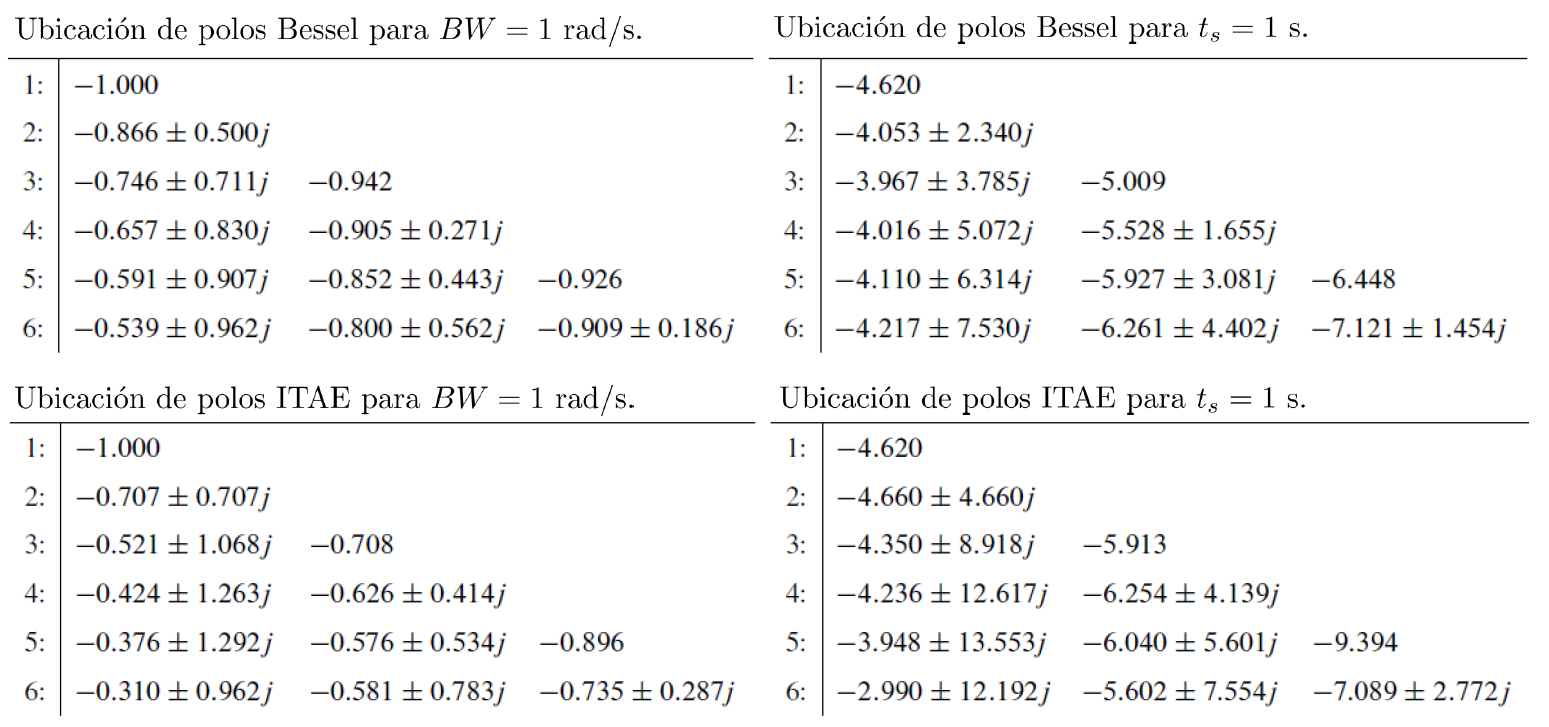

En mi caso prefiero calcularlo con comando pole, Como la función de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.

tsdes=10   % Tiempo de asentamiento deseado 23.3 minutos aprox.

tsdes = 10

zita=1  %define si es críticamente amortiguado.

zita = 1

fna=4/(tsdes*zita) %wn=frecNaturalAmortiguada

fna = 0.4000

sistReferencia=tf([0 0 1],[1 2*zita*fna fna^2]);
polos=[pole(sistReferencia);-15] %Como la f de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.

polos =   -0.4000 + 0.0000i
  -0.4000 - 0.0000i
 -15.0000 + 0.0000i


%polos=[-3.967+3.785i -3.967-3.785i -5.009]    %Polo sacado de tabla.
mat_K=acker(sustitu_mat_lin_A,sustitu_mat_lin_B,polos)  %calcula ganancia que tiene el estado en x3 para que tienda a una referencia

mat_K =    -0.0536   -0.0018   13.5215


## Simulación con Resolución de ODE

Condiciones iniciales y periodo de muestreo

No funcionó con el polo calculado asi que uso el de la tabla.

Tsim=30;            % Tiempo total de la simulación
x_0=[0 0 0];
%pos_inic=0; vel_inic=0; x_0=[pos_inic vel_inic]'; %Condiciones iniciales
Ts=0.01;             % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
ref=[x1_ss x2_ss x3_ss]'; %era 0.2 Referencia de simulación
u=0;                % Señal de control para el primer instante de muestreo.
x_sim=zeros(Ns,3); usim=zeros(Ns,1); % Tamaño de vectores definido

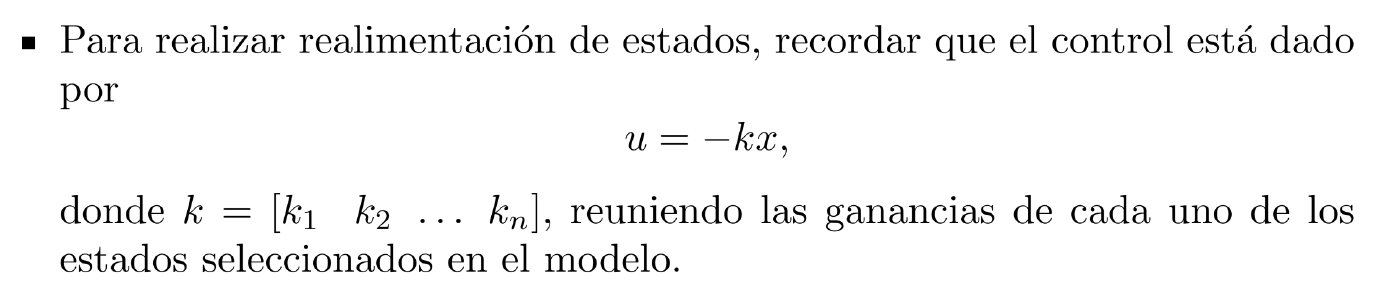

Ciclo de simulación:

for i=1:Ns
    [t,xd]=ode45('plantafcn',Ts,x_0,[],u);   %tenia kbb,u Simular la planta para un Ts.
    xmed=xd(end,:)';  % Medir estados (la última señal se toma a los Ts segundos).
    error=ref-xmed;
    u=-mat_K*error;       % Cálculo del control y se envía a la planta.
    x_0=xmed;        % Condiciones inciales para la próxima iteración
    x_sim(i,:)=xmed';    % Solo almacenar los estados para graficar.
    usim(i,:)=u;     % Solo almacenar la señal de control para graficar.
end

#### Grafica:

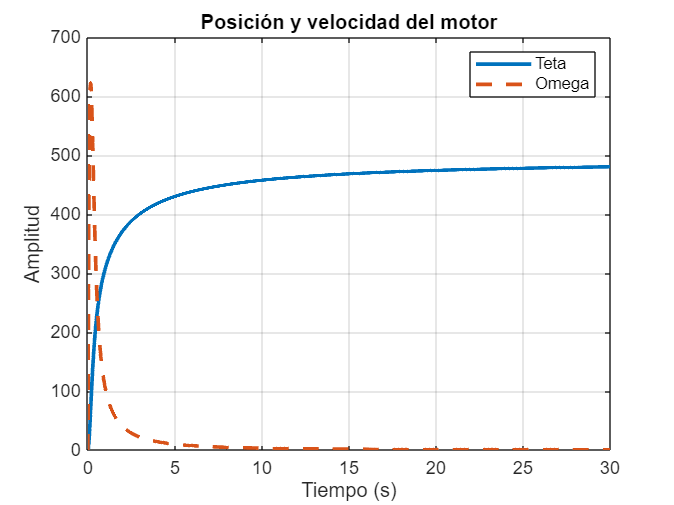

time=0:Ts:Ns*Ts-Ts;
figure; %subplot(2,1,1); 
plot(time,abs(x_sim(:,1)),'LineWidth', 2); title('Posición y velocidad del motor');
xlabel('Tiempo (s)'); ylabel('Amplitud (Voltios)'); grid on;
hold on
plot(time,abs(x_sim(:,2)),'--','LineWidth', 2); title('Posición y velocidad del motor');
xlabel('Tiempo (s)'); ylabel('Amplitud'); grid on; legend('Teta','Omega');
hold off

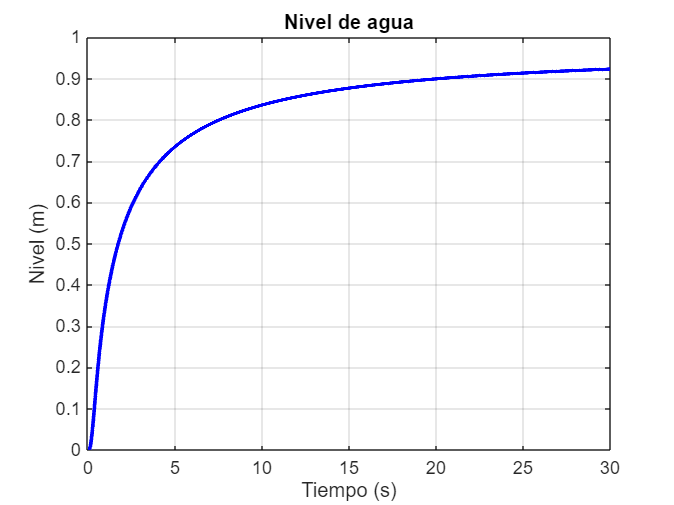

%subplot(2,1,2);
plot(time,abs(x_sim(:,3)),'b','LineWidth', 2); title('Nivel de agua');
xlabel('Tiempo (s)'); ylabel('Nivel (m)'); grid on;

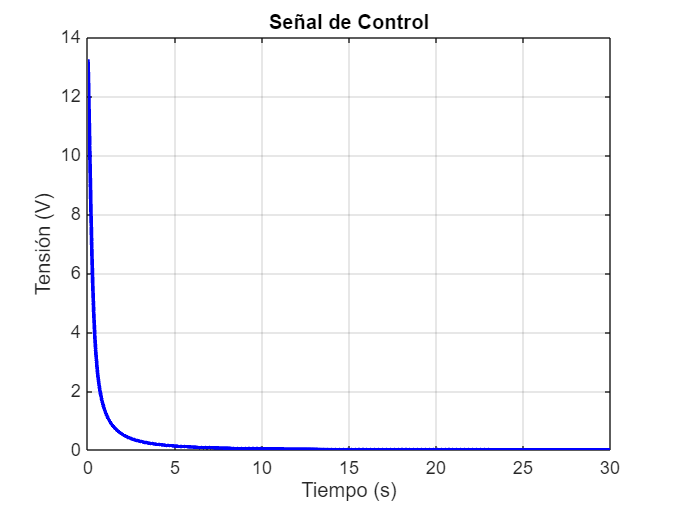


figure;
plot(time,abs(usim),'b','LineWidth', 2); title('Señal de Control');
xlabel('Tiempo (s)'); ylabel('Tensión (V)'); grid on;